# Diffusion of Optically Pumped Atoms 

## Background

We consider an atomic ensemble (i.e., a large number of atoms) confined in a container. Each atom has $M$ internal eigenstates (e.g., quantum mechanical energy levels, usually, denoted by $|\psi_i \rangle$ for $i=1,\text{ }2,\ldotp \ldotp \ldotp ,M$). The overall state of the atomic ensemble is described by a column vector 


$$\rho \left(\mathbf{r}\right)={\left\lbrack \rho_1 \left(\mathbf{r}\right),\rho_2 \left(\mathbf{r}\right),\ldotp \ldotp \ldotp ,\rho_M \left(\mathbf{r}\right)\right\rbrack }^T ,$$


where each component $\rho_i \left(\mathbf{r}\right)$ is the probability for finding an atom at position $\mathbf{r}$ and in the $i$-th internal state.

We consider the following two processes:

- Quantum evolution. The atoms change from one internal state $|\psi_i \rangle$ to another $|\psi_j \rangle$ at a certain rate. The quantum transition among the $M$ internal states is described by a $M\times M$ matrix $G$ as


$${\left\lbrack \frac{\partial \rho }{\partial t}\right\rbrack }_{\text{transition}} =−G\left(\mathbf{r}\right)\rho \ldotp$$


              The matrix element $G_{i\text{ }j}$ ($i,j=1,\ldotp \ldotp \ldotp ,M$) is the transition rate from state $|\psi_i \rangle$ to $|\psi_i \rangle$.

- Spatial diffusion. As the atomic state $\rho \left(\mathbf{r}\right)$ also depends on spatial coordinate $\mathbf{r}$, the atoms will diffuse from the location with higher density to lower density, which is described by a standard diffusion equation with a scalar diffusion constant $D$


$${\left\lbrack \frac{\partial \rho }{\partial t}\right\rbrack }_{diffusion} =D{\text{ }\nabla }^2 \rho \ldotp$$


## The Problem

Within a three-dimensional domain $\Omega$, the full atomic evolution is governed by 


$$\frac{\partial \rho }{\partial t}=D{\text{ }\nabla }^2 \rho −G\left(\mathbf{r}\right)\rho ,\text{ }\text{ }\text{for}\text{ }\mathbf{r}\in \text{ }\Omega \ldotp \text{                   }\left(1\right)$$


The initial condition is that all the internal states are equally populated, i.e.,


$$\rho \left(t=0\right)=\frac{1}{M}{\left\lbrack 1,1,\ldotp \ldotp \ldotp ,1\right\rbrack }^T \equiv \varphi_0 ,\text{ }\text{for}\text{ }\text{all}\text{ }\mathbf{r}\in \text{ }\Omega \ldotp \text{                         }\left(2\right)$$


The boundary condition, which depends on the physical condition, can be either the Neumann type


$$\hat{\mathbf{n}} \cdot \nabla \rho =0,\text{ }\text{ }\text{for}\text{  }\mathbf{r}\in \text{ }\partial \Omega ,\text{                        }\left(3\right)$$


with  the unit normal vector $\hat{\mathbf{n}}$ of the boundary, or the Dirichlet type


$$\rho \left(\mathbf{r}\right)=\varphi_0 ,\text{ }\text{ }\text{for}\text{  }\mathbf{r}\in \text{ }\partial \Omega \ldotp \text{                          }\left(4\right)$$


Find the solution $\rho \left(\mathbf{r},t\right)$ of Eq.(1), together with the initial condition Eq.(2) and the boundary condition Eq.(3) or Eq.(4), using FEM on a cubic domain (with length of side $L=1\text{ }\text{cm}$).

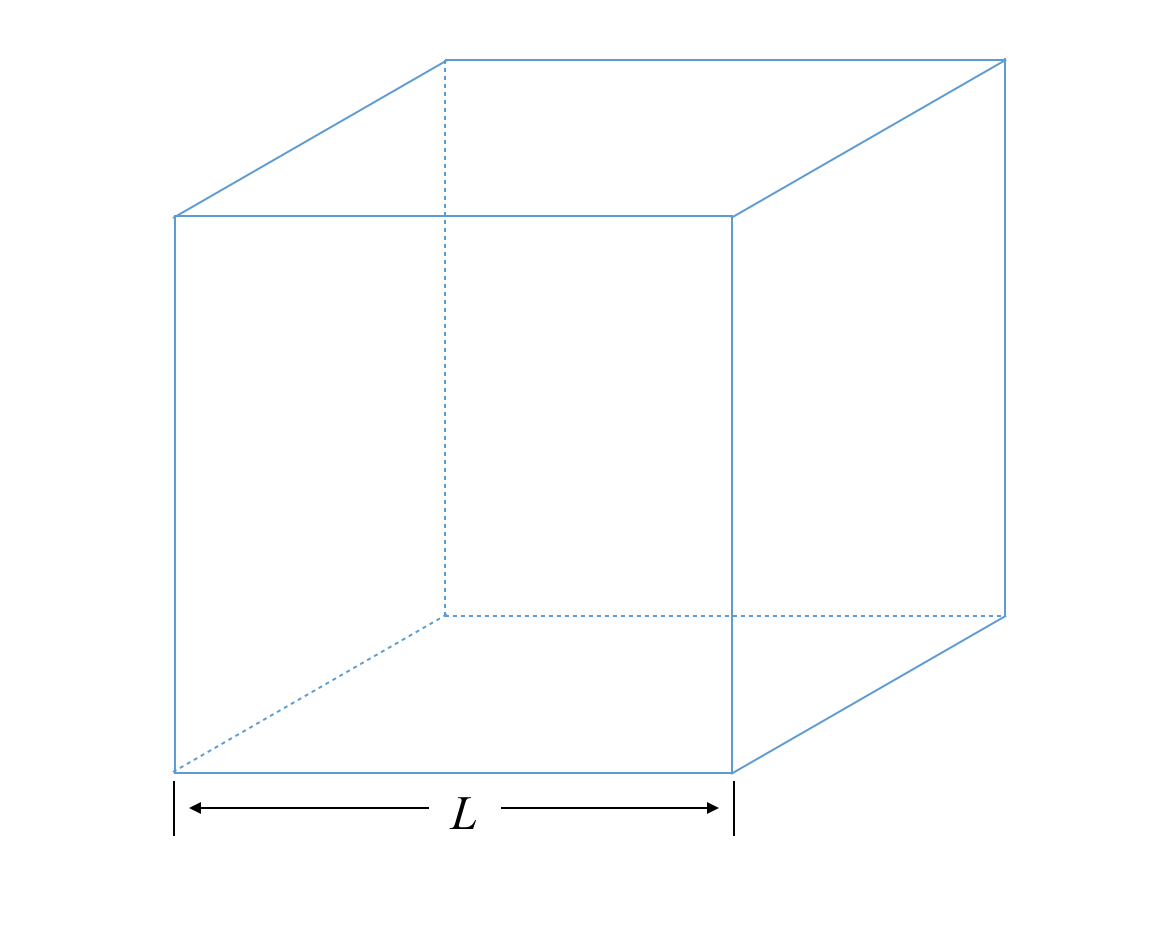

The diffusion constant is 


$$D=0\ldotp 1\text{ }{cm}^2 /s\ldotp \text{                                         }\left(5\right)$$
 

Consider the atom has $M=8$ internal states. The $8\times 8$ matrix $G$ can be decomposed as the product of a scalar function $P\left(\mathbf{r}\right)$ and a constant matrix $G_0$, i.e.  $G\left(\mathbf{r}\right)=P\left(\mathbf{r}\right)G_0$, where $P_0 \left(\mathbf{r}\right)$ describes the inhomogeneity of the matrix $G\left(\mathbf{r}\right)$


$$P\left(\mathbf{r}\right)=P_0 exp\left\lbrack −\frac{x^2 +y^2 }{w^2 }\right\rbrack ,\text{               }\left(6\right)$$


with typical values$\text{ }P_0 =1\text{ }s^{−1}$,  and $w=0\ldotp 2\text{ }\text{cm}$. 

The constant matrix $G_0$ consists of two components $C_0$ and $D_0$, 


$$G_0 =C_0 +\alpha \text{ }D_0 ,\text{                                   }\left(7\right)$$


where $\alpha >0$ is a real variable with the typical value $\alpha =0\ldotp 5$. The matrices $C_0$and $D_0$ have the following form

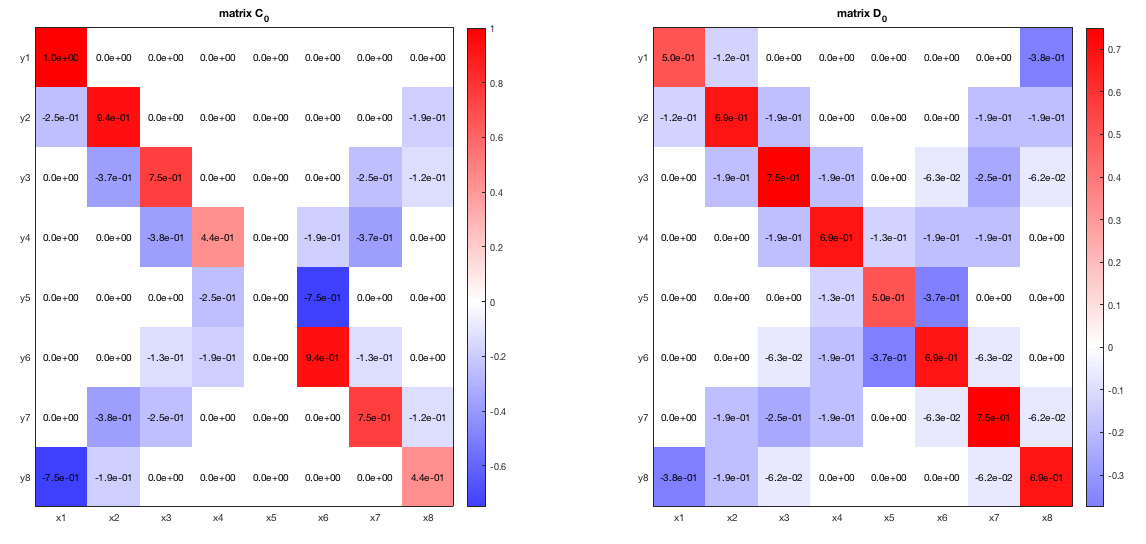

These matrices are stored in a matlab data file ('DifussionFEM.mat'), and you can load them by executing the command 

load('DiffusionFEM.mat');

## Task

Solve the following problems step-by-step, with increasing degree of difficulty

- Neglect the spatial dependence of $G$ [assuming $w\to +\infty$ in Eq.(6)], and consider the steady-state solution ($\partial \rho /\partial t=0$). Solve the problem using FEM, and compare the numerical results with the  exact solution by separation of variables method;

- Find the steady-state solution ($\partial \rho /\partial t=0$) of Eq.(1) with parameters $L=1\text{ }cm$, $D=0\ldotp 1\text{ }{\text{cm}}^2 /s$, $P_0 =1\text{ }s^{−1}$, $w=0\ldotp 2\text{ }cm$, and $\alpha =0\ldotp 5$,  under different boundary conditions Eq.(3) or Eq.(4);

- Solve the full evolution problem under boundary condition Eq.(3) and Eq.(4), respectively;

- Compare the computation efficiency of the $h$-version and $p$-version FEM on solving above problems.

## Possible Extensions

- **Different geometry**: in real experiments, the domain can be of various shape, like cubic, sphercial, cylindrical, pyramidical, or even more complicated shape. The $p$-version FEM may not so convenient as in the case of a cubic domain. Some commercial software may be useful in solving realistic problems. Try to build a model in, e.g., Comsol Multiphysics, and compare the results in the cubic domain obtained above;

- **Non-linear problem**: in realistic problems, the matrix $G\left(\mathbf{r}\right)$ in Eq.(1)  can be much more sophisticated than that we defined in Eq.(7). Indeed, the value of $G$ depends on the value of $\rho \text{ }$, i.e., $G=G\left\lbrack \mathbf{r},\rho \left(\mathbf{r}\right)\right\rbrack$. In this case, Eq.(1) becomes a non-linear equation. The exact form of $G\left\lbrack \mathbf{r},\text{ }\rho \left(\mathbf{r}\right)\right\rbrack$ was dicussed in  S. Appelt, et. al., Physical Review A **58**, 1412 (1998) [see Eq. (96)]. We have developed numerical code, according to this reference, for calculating the explicit values of $G\left\lbrack \mathbf{r},\rho \left(\mathbf{r}\right)\right\rbrack$. Come to us if you want to try the non-linear problem. 